fc = 6e9;                             % carrier frequency (Hz)
bsPosition = [22.287495, 114.140706]; % lat, lon
bsAntSize = [2 2];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg
uePosition = [22.287323,114.140859];  % lat, lon
ueAntSize = [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [100 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
reflectionsOrder = 1;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 15; % subcarrier spacing
NRB = 52; % number of resource blocks, 10 MHz bandwidth

if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","hongkong.osm");    
end

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);

ueSite = rxsite("Name","UE", ...
    "Latitude",uePosition(1),"Longitude",uePosition(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ueArrayOrientation(1:2));

show(bsSite);
show(ueSite);

pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
rays = raytrace(bsSite,ueSite,pm,"Type","pathloss");

plot(rays{1})

pathToAs = [rays{1}.PropagationDelay]-min([rays{1}.PropagationDelay]);  % Time of arrival of each ray (normalized to 0 sec)
avgPathGains  = -[rays{1}.PathLoss];                                    % Average path gains of each ray
pathAoDs = [rays{1}.AngleOfDeparture];                                  % AoD of each ray
pathAoAs = [rays{1}.AngleOfArrival];                                    % AoA of each ray
isLOS = any([rays{1}.LineOfSight]);                                     % Line of sight flag

channel = nrCDLChannel;
channel.DelayProfile = 'Custom';
channel.PathDelays = pathToAs;
channel.AveragePathGains = avgPathGains;
channel.AnglesAoD = pathAoDs(1,:);       % azimuth of departure
channel.AnglesZoD = 90-pathAoDs(2,:);    % channel uses zenith angle, rays use elevation
channel.AnglesAoA = pathAoAs(1,:);       % azimuth of arrival
channel.AnglesZoA = 90-pathAoAs(2,:);    % channel uses zenith angle, rays use elevation
channel.HasLOSCluster = isLOS;
channel.CarrierFrequency = fc;
channel.NormalizeChannelOutputs = false; % do not normalize by the number of receive antennas, this would change the receive power
channel.NormalizePathGains = false;      % set to false to retain the path gains

c = physconst('LightSpeed');
lambda = c/fc;

% UE array (single panel)
ueArray = phased.NRRectangularPanelArray('Size',[ueAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
ueArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element
channel.ReceiveAntennaArray = ueArray;
channel.ReceiveArrayOrientation = [ueArrayOrientation(1); (-1)*ueArrayOrientation(2); 0];  % the (-1) converts elevation to downtilt

% Base station array (single panel)
bsArray = phased.NRRectangularPanelArray('Size',[bsAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
bsArray.ElementSet = {phased.NRAntennaElement('PolarizationAngle',-45) phased.NRAntennaElement('PolarizationAngle',45)}; % cross polarized elements
channel.TransmitAntennaArray = bsArray;
channel.TransmitArrayOrientation = [bsArrayOrientation(1); (-1)*bsArrayOrientation(2); 0];   % the (-1) converts elevation to downtilt

ofdmInfo = nrOFDMInfo(NRB,SCS);

channel.SampleRate = ofdmInfo.SampleRate;

channel.ChannelFiltering = false;
[pathGains,sampleTimes] = channel();

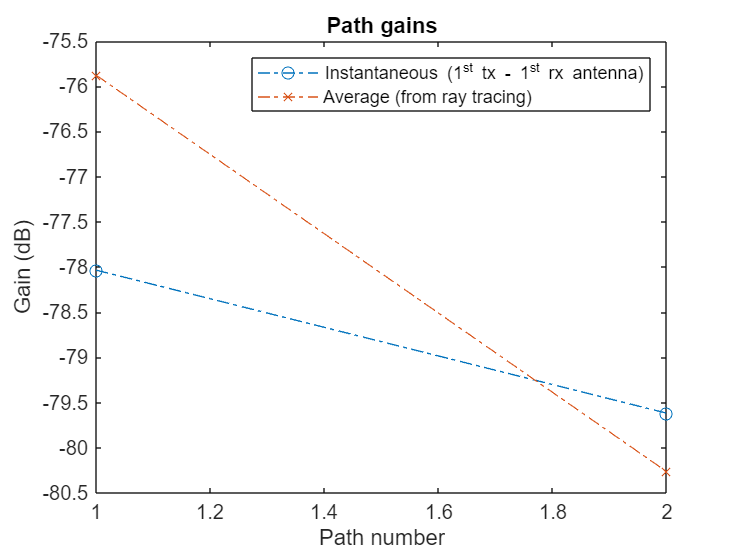

pg=permute(pathGains,[2 1 3 4]); % first dimension is the number of paths
if isLOS
    % in LOS cases sum the first to paths, they correspond to the LOS ray
    pg = [sum(pg(1:2,:,:,:)); pg(3:end,:,:,:)];
end
pg = abs(pg).^2;
plot(pow2db(pg(:,1,1,1)),'o-.');hold on
plot(avgPathGains,'x-.');hold off
legend("Instantaneous (1^{st} tx - 1^{st} rx antenna)","Average (from ray tracing)")
xlabel("Path number"); ylabel("Gain (dB)")
title('Path gains')

pathFilters = getPathFilters(channel);
nSlot = 0;
[offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
hest = nrPerfectChannelEstimate(pathGains,pathFilters,NRB,SCS,nSlot,offset,sampleTimes);

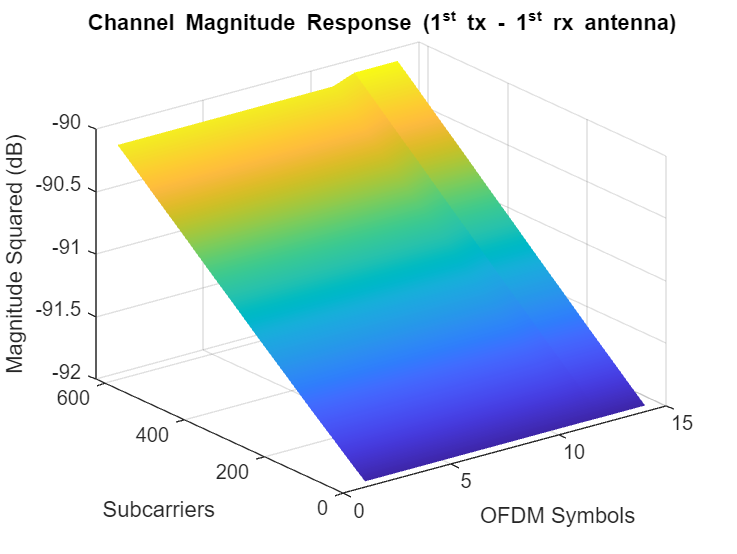

surf(pow2db(abs(hest(:,:,1,1)).^2));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
title('Channel Magnitude Response (1^{st} tx - 1^{st} rx antenna)');

function [wtx,wrx,D] = getBeamformingWeights(hEst,nLayers,scOffset,noRBs)
% Get beamforming weights given a channel matrix hEst and the number of
% layers nLayers. One set of weights is provided for the whole bandwidth.
% The beamforming weights are calculated using singular value (SVD)
% decomposition.
%
% Only part of the channel estimate is used to get the weights, this is
% indicated by an offset SCOFFSET (offset from the first subcarrier) and a
% width in RBs (NORBS).

% Average channel estimate
[~,~,R,P] = size(hEst);
%H = permute(mean(reshape(hEst,[],R,P)),[2 3 1]);

scNo = scOffset+1;
hEst = hEst(scNo:scNo+(12*noRBs-1),:,:,:);
H = permute(mean(reshape(hEst,[],R,P)),[2 3 1]);

% SVD decomposition
[U,D,V] = svd(H);
wtx = V(:,1:nLayers).';
wrx = U(:,1:nLayers)';
end

nLayers = 1;
scOffset = 0;   % no offset
noRBs = 1;      % average channel conditions over 1 RB to calculate beamforming weights
[wbs,wue,~] = getBeamformingWeights(hest,nLayers,scOffset,noRBs);

% Plot UE radiation pattern
ueSite.Antenna = clone(channel.ReceiveAntennaArray); % need a clone, otherwise setting the Taper weights would affect the channel array
ueSite.Antenna.Taper = wue;
pattern(ueSite,fc,"Size",4);

% Plot BS radiation pattern
bsSite.Antenna = clone(channel.TransmitAntennaArray); % need a clone, otherwise setting the Taper weights would affect the channel array
bsSite.Antenna.Taper = wbs;
pattern(bsSite,fc,"Size",5);